## Main Script

In this script whole procedure of model identification and control is held.

### Initialization

clc; clear all; close all;
addpath(genpath('flexy2'))
addpath(genpath('identification'))

#### Open Communication

a = Flexy2;

Searching COM ports ...
OCL_Flexy_v2.0 found on port /dev/cu.usbmodem11201
Waiting for connection ...
Connection established.


a.calibrate
calibrate = 0;
Port = a.ComPort;

Ts = 0.01;
start_speed = 0;

env_vars = readvars('../.env','FileType','delimitedtext');

sender = env_vars{1};
my_password = env_vars{2};
recipient = env_vars{3};

K = 0.7869;
T = 0.4127;
num = K;
den = [T 1];

### Control Procedure

#### Step Testing

Elapsed time is 0.010596 seconds.


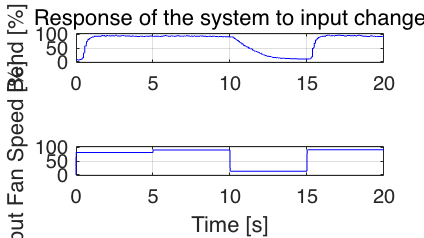

data = stepfan(a,'StepAmpPerc',20, ...
                'NumSteps',4, 'Ts', Ts, ...
                'InputOffset', start_speed,'Plot',true);

#### Save identification data

filetime = datestr(now,'yyyymmddHHMMSS');
save(sprintf('%s_fan_%s.mat',filetime, 'data'), 'data')

#### Make preprocessing

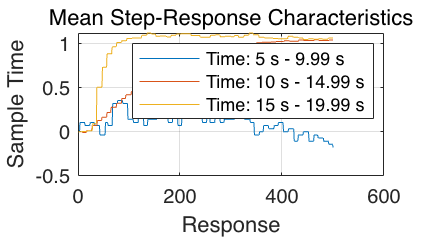

[u_mean, y_mean, idx] = preprocessData(data);

#### Identify system parameters of the specified order 

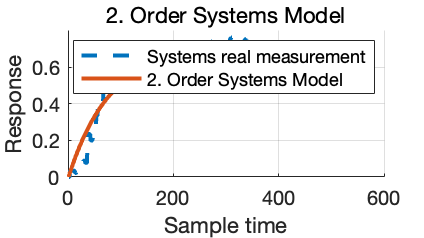

idtf = recursiveLeastSquares(u_mean, y_mean, Ts, 1, 2, 'PlotConv', false);

#### Plot open loop simulation over input data

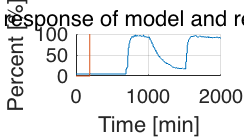

f = figure;
f.Position = [100 100 960 540];
hold on
grid on
title('Step response of model and real system', 'FontWeight','Normal')
xlabel('Time [min]')
ylabel('Percent [%]')
ylim([0,100])
plot(data.y);
plot(lsim(idtf.SysCT,data.u,data.t))

#### Open Control Scheme

open_system('PID.slx');

%out = sim('PID.slx')